# Lab4

% Load parameters
run('balrob_params.m');

## State-variable estimation

### 5.2.1

% Cut-off frequency
stvar_est.fc = 0.35;

% LPF H(s)
stvar_est.Hs = tf([1], [1/stvar_est.fc 1]);

% H(s) --> H(z) FORWARD [s = (z-1)/Ts]
stvar_est.Hz = tf([Ts], [1/stvar_est.fc Ts-1/stvar_est.fc], Ts);
[stvar_est.Hz_Num, stvar_est.Hz_Den] = tfdata(stvar_est.Hz);
stvar_est.Hz_Num = cell2mat(stvar_est.Hz_Num);
stvar_est.Hz_Den = cell2mat(stvar_est.Hz_Den);


% Discrete-time real derivative
stvar_est.realDerivative_Num_z = [1 0 0 -1];
stvar_est.realDerivative_Den_z = [3*Ts 0 0 0];

## State-space discretization (A, B, C) --> ()

% State-space A, B
state_space.A = [[0 0; 0 0] eye(2); -inv(linmodel.M)*linmodel.G -inv(linmodel.M)*linmodel.Fv1];
state_space.B = 2*gbox.N*mot.Kt/mot.R*[[0 0; 0 0]; inv(linmodel.M)]*[1; -1];
state_space.C = [1 0 0 0];

% Discretized state-space Phi, Gamma, H
[state_space.Phi, state_space.Gamma, state_space.H] = ssdata(c2d(ss(state_space.A, state_space.B, state_space.C, 0), Ts, 'zoh'));

## Nx, Nu

X = linsolve([state_space.Phi-eye(4) state_space.Gamma; state_space.H 0], [0;0;0;0;1]);
Nx = X(1:4);
Nu = X(5);

## LQR --> K [NOMINAL]

### 5.2.2

% BRYSON'S RULE: gamma_bar, theta_bar, u_bar
lqr_nominal.gamma_bar = pi/18;
lqr_nominal.theta_bar = pi/360;
lqr_nominal.u_bar = 1;

% Q, r
lqr_nominal.Q = diag([1/lqr_nominal.gamma_bar^2 1/lqr_nominal.theta_bar^2 0 0]);
lqr_nominal.r = 1/lqr_nominal.u_bar^2;

% Rho
lqr_nominal.rho_1 = 500;
lqr_nominal.rho_2 = 5000;

% K_1
lqr_nominal.K_1 = dlqr(state_space.Phi, state_space.Gamma, lqr_nominal.Q, lqr_nominal.r*lqr_nominal.rho_1);

% K_2
lqr_nominal.K_2 = dlqr(state_space.Phi, state_space.Gamma, lqr_nominal.Q, lqr_nominal.r*lqr_nominal.rho_2);


### 5.2.3

% Open Simulink model
open_system('Simulink/BalRobModel.slx');

#### Simulation results $\bf{X_0 = [0 \ \frac{\pi}{36} \ 0 \ 0]}$, [No disturbance]

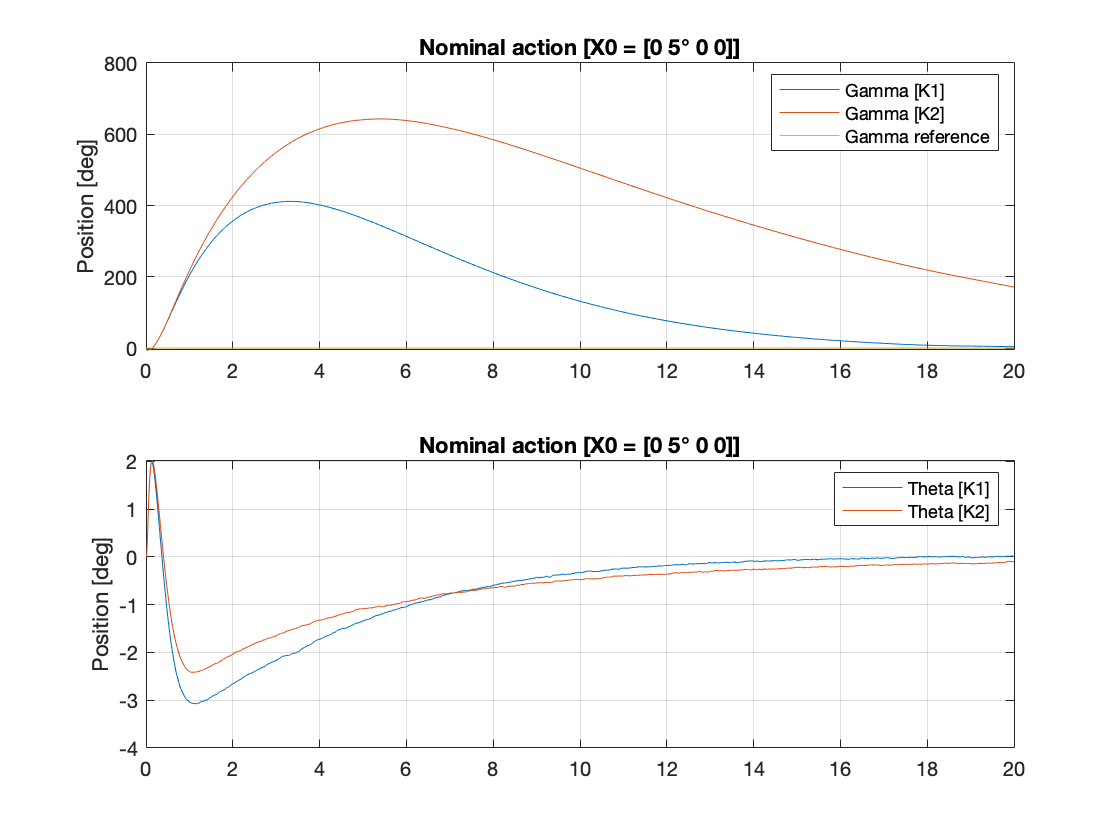

%% k1
% Set parameters
set_param('BalRobModel', ...
    'SolverType', 'Fixed-step', ...
    'Solver', 'FixedStepAuto', ...
    'StopTime', '20');
% Reference
set_param('BalRobModel/gam_ref [deg]','Value','0');

% State-space Controller
set_param('BalRobModel/Enable Integral','Value','0'); % Nominal action ON
set_param('BalRobModel/State-space Controller/Input feedforward gain','gain','Nu'); % Input feedforward gain
set_param('BalRobModel/State-space Controller/State feedforward gain','gain','Nx'); % State feedforward gain
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_nominal.K_1'); % State feedback gain
set_param('BalRobModel/State-space Controller/Ki','Gain','0'); % Integral gain = 0;

% Initial conditions
lqr_nominal.x0 = [0 5 0 0]; % [deg]
set_param('BalRobModel/X0 [deg]','Value','lqr_nominal.x0'); % x0 = [0 5 0 0]

% Disturbance
set_param('BalRobModel/Disturbance','Time','0','Before','0','After','0'); % No disturbance


% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_nominal.t1 = simres.time; % Time vector 
lqr_nominal.gam1 = simres.signals(1).values(:,1); % Gamma
lqr_nominal.thh1 = simres.signals(1).values(:,2); % Theta
lqr_nominal.refgam1 = simres.signals(1).values(:,3); % Ref gamma

%% K2
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_nominal.K_2'); % State feedback gain

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_nominal.t2 = simres.time; % Time vector 
lqr_nominal.gam2 = simres.signals(1).values(:,1); % Gamma
lqr_nominal.thh2 = simres.signals(1).values(:,2); % Theta
lqr_nominal.refgam2 = simres.signals(1).values(:,3); % Ref gamma

% Plot simulation results
figure
subplot(2,1,1)
plot(lqr_nominal.t1, lqr_nominal.gam1);
hold on;
plot(lqr_nominal.t2, lqr_nominal.gam2);
hold on;
plot(lqr_nominal.t2, lqr_nominal.refgam2);
ylabel('Position [deg]');
grid on;
title('Nominal action [X0 = [0 5° 0 0]]');
legend('Gamma [K1]', 'Gamma [K2]', 'Gamma reference');

subplot(2,1,2)
plot(lqr_nominal.t1, lqr_nominal.thh1);
hold on;
plot(lqr_nominal.t2, lqr_nominal.thh2);
ylabel('Position [deg]');
grid on;
title('Nominal action [X0 = [0 5° 0 0]]');
legend('Theta [K1]', 'Theta [K2]');

#### Simulation results $\bf{X_0 = [0 \ 0 \ 0 \ 0]}$, [No disturbance]

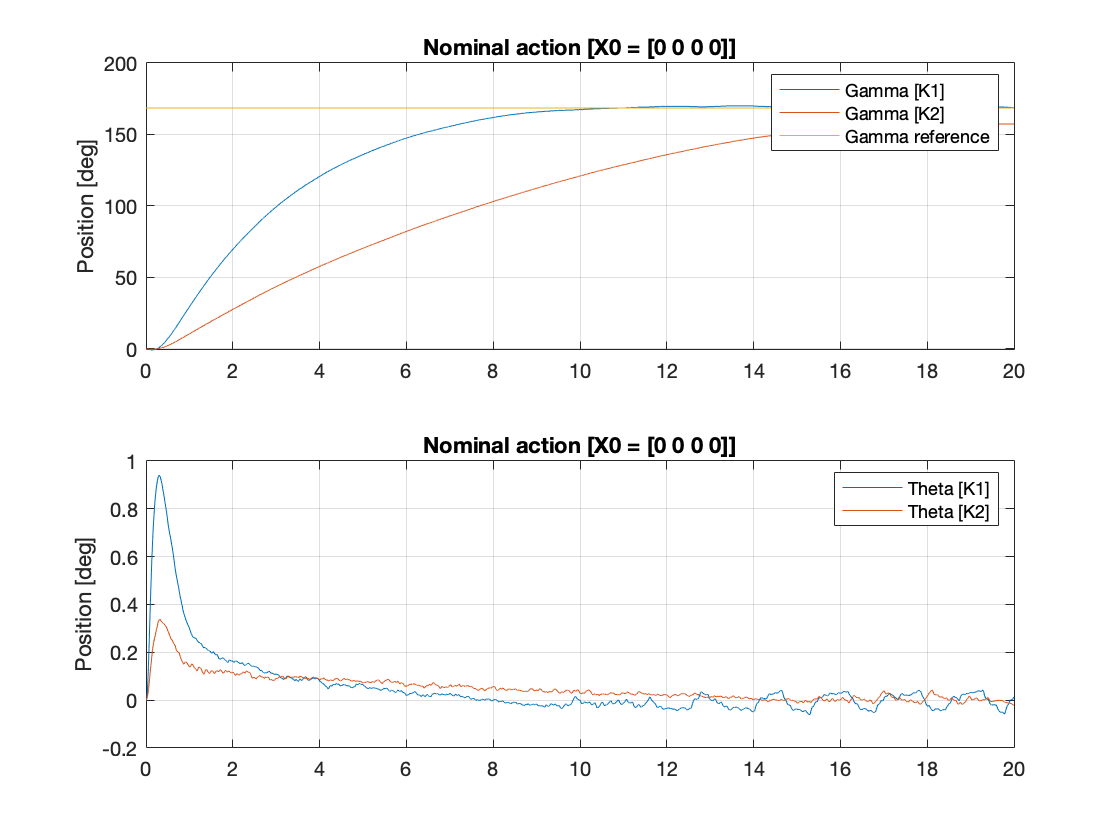

%% K1
% Set parameters
set_param('BalRobModel', ...
    'SolverType', 'Fixed-step', ...
    'Solver', 'FixedStepAuto', ...
    'StopTime', '20');
% Reference
set_param('BalRobModel/gam_ref [deg]','Value','0.1/wheel.r*rad2deg');

% State-space controller
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_nominal.K_1'); % State feedback gain

% Initial conditions
lqr_nominal.x0 = [0 0 0 0]; % [deg]
set_param('BalRobModel/X0 [deg]','Value','lqr_nominal.x0'); % x0 = [0 0 0 0]

% Disturbance
set_param('BalRobModel/Disturbance','Time','10','Before','0','After','0'); % No disturbance

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_nominal.t1 = simres.time; % Time vector 
lqr_nominal.gam1 = simres.signals(1).values(:,1); % Gamma
lqr_nominal.thh1 = simres.signals(1).values(:,2); % Theta
lqr_nominal.refgam1 = simres.signals(1).values(:,3); % Ref gamma

%% K2
% State-space controller
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_nominal.K_2'); % State feedback gain

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_nominal.t2 = simres.time; % Time vector 
lqr_nominal.gam2 = simres.signals(1).values(:,1); % Gamma
lqr_nominal.thh2 = simres.signals(1).values(:,2); % Theta
lqr_nominal.refgam2 = simres.signals(1).values(:,3); % Ref gamma

% Plot simulation results
figure
subplot(2,1,1)
plot(lqr_nominal.t1, lqr_nominal.gam1);
hold on;
plot(lqr_nominal.t2, lqr_nominal.gam2);
hold on;
plot(lqr_nominal.t2, lqr_nominal.refgam2);
ylabel('Position [deg]');
grid on;
title('Nominal action [X0 = [0 0 0 0]]');
legend('Gamma [K1]', 'Gamma [K2]', 'Gamma reference');

subplot(2,1,2)
plot(lqr_nominal.t1, lqr_nominal.thh1);
hold on;
plot(lqr_nominal.t2, lqr_nominal.thh2);
ylabel('Position [deg]');
grid on;
title('Nominal action [X0 = [0 0 0 0]]');
legend('Theta [K1]', 'Theta [K2]');

#### Simulation results $\bf{X_0 = [0 \ 0 \ 0 \ 0]}$, [Disturbance = 5V]

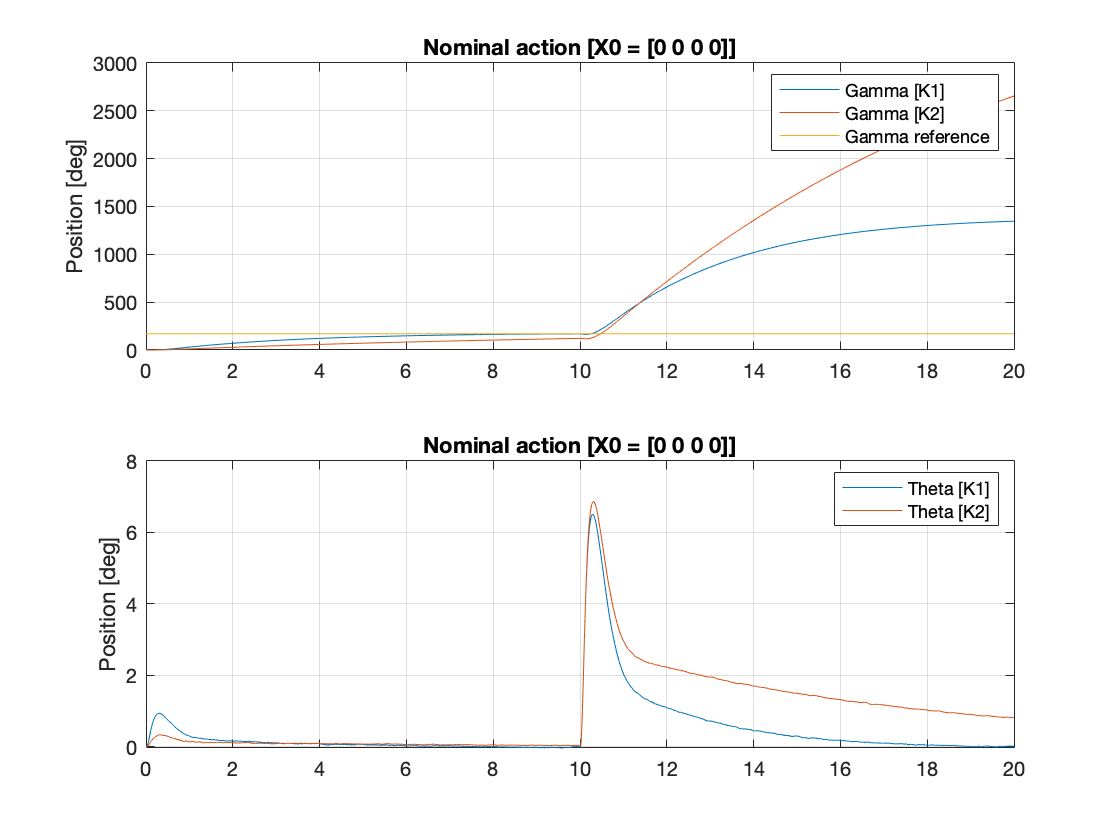

%% k1
% Set parameters
set_param('BalRobModel', ...
    'SolverType', 'Fixed-step', ...
    'Solver', 'FixedStepAuto', ...
    'StopTime', '20');
% Reference
set_param('BalRobModel/gam_ref [deg]','Value','0.1/wheel.r*rad2deg');

% State-space controller
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_nominal.K_1'); % State feedback gain

% Initial conditions
lqr_nominal.x0 = [0 0 0 0]; % [deg]
set_param('BalRobModel/X0 [deg]','Value','lqr_nominal.x0'); % x0 = [0 0 0 0]

% Disturbance
set_param('BalRobModel/Disturbance','Time','10','Before','0','After','5/drv.duty2V'); % Disturbance = 5V

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_nominal.t1 = simres.time; % Time vector 
lqr_nominal.gam1 = simres.signals(1).values(:,1); % Gamma
lqr_nominal.thh1 = simres.signals(1).values(:,2); % Theta
lqr_nominal.refgam1 = simres.signals(1).values(:,3); % Ref gamma

% k2
% State-space controller
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_nominal.K_2'); % State feedback gain

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_nominal.t2 = simres.time; % Time vector 
lqr_nominal.gam2 = simres.signals(1).values(:,1); % Gamma
lqr_nominal.thh2 = simres.signals(1).values(:,2); % Theta
lqr_nominal.refgam2 = simres.signals(1).values(:,3); % Ref gamma

% Plot simulation results
figure
subplot(2,1,1)
plot(lqr_nominal.t1, lqr_nominal.gam1);
hold on;
plot(lqr_nominal.t2, lqr_nominal.gam2);
hold on;
plot(lqr_nominal.t2, lqr_nominal.refgam2);
ylabel('Position [deg]');
grid on;
title('Nominal action [X0 = [0 0 0 0]]');
legend('Gamma [K1]', 'Gamma [K2]', 'Gamma reference');

subplot(2,1,2)
plot(lqr_nominal.t1, lqr_nominal.thh1);
hold on;
plot(lqr_nominal.t2, lqr_nominal.thh2);
ylabel('Position [deg]');
grid on;
title('Nominal action [X0 = [0 0 0 0]]');
legend('Theta [K1]', 'Theta [K2]');

## LQR --> K [ROBUST]

### 5.2.4

% Phi_e, Gamma_e
lqr_robust.Phie = [1 state_space.H; [0;0;0;0] state_space.Phi];
lqr_robust.Gammae = [0; state_space.Gamma];

% BRYSON'S RULE: gamma_bar, theta_bar, u_bar
lqr_robust.gamma_bar = pi/18;
lqr_robust.theta_bar = pi/360;
lqr_robust.u_bar = 1;

% Q, r
lqr_robust.q11_1 = 0.1;
lqr_robust.q11_2 = 1;
lqr_robust.Q_1 = diag([lqr_robust.q11_1 1/lqr_robust.gamma_bar^2 1/lqr_robust.theta_bar^2 0 0]);
lqr_robust.Q_2 = diag([lqr_robust.q11_2 1/lqr_robust.gamma_bar^2 1/lqr_robust.theta_bar^2 0 0]);
lqr_robust.r = 1/lqr_robust.u_bar^2;

% Rho
lqr_robust.rho = 500;

% Ke1
lqr_robust.Ke_1 = dlqr(lqr_robust.Phie, lqr_robust.Gammae, lqr_robust.Q_1, lqr_robust.r*lqr_robust.rho);

% Ki1, K1
lqr_robust.Ki_1 = lqr_robust.Ke_1(1);
lqr_robust.K_1 = lqr_robust.Ke_1(2:5);

% Ke2
lqr_robust.Ke_2 = dlqr(lqr_robust.Phie, lqr_robust.Gammae, lqr_robust.Q_2, lqr_robust.r*lqr_robust.rho);

% Ki2, K2
lqr_robust.Ki_2 = lqr_robust.Ke_2(1);
lqr_robust.K_2 = lqr_robust.Ke_2(2:5);

#### 5.2.5

#### Simulation results $\bf{X_0 = [0 \ \frac{\pi}{36} \ 0 \ 0]}$, [No disturbance]

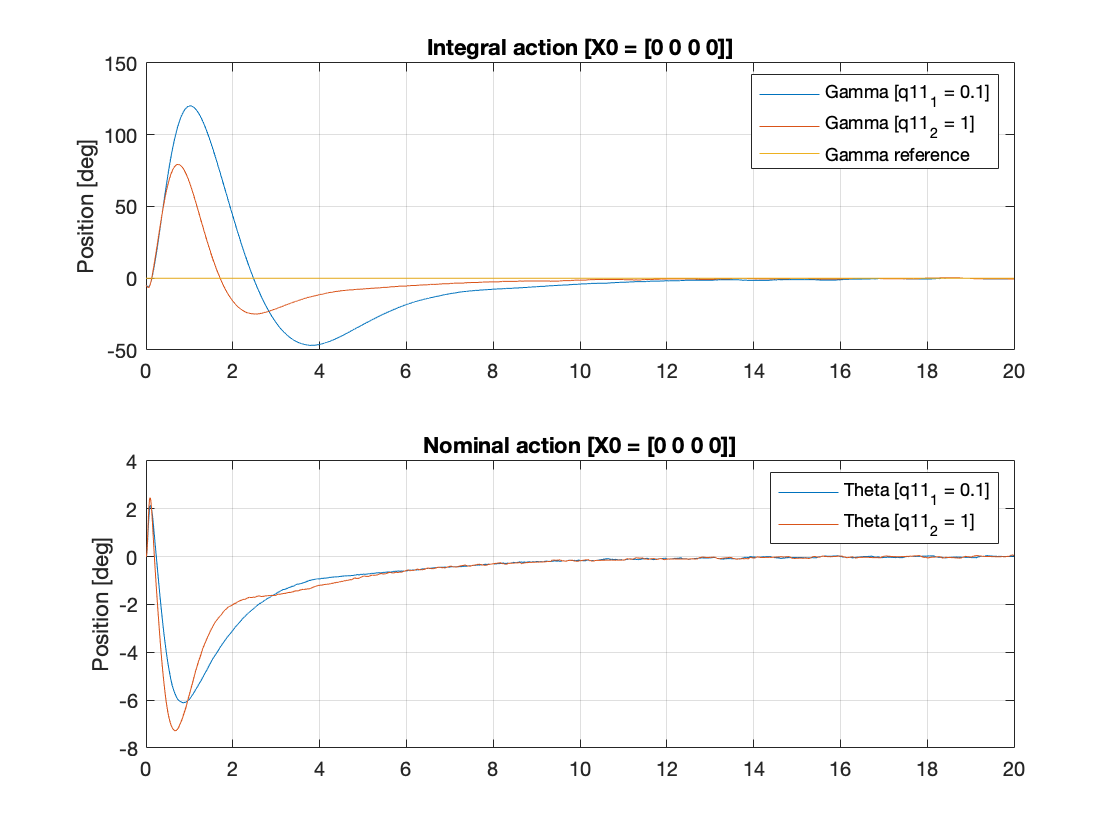

%% k1
% Set parameters
set_param('BalRobModel', ...
    'SolverType', 'Fixed-step', ...
    'Solver', 'FixedStepAuto', ...
    'StopTime', '20');
% Reference
set_param('BalRobModel/gam_ref [deg]','Value','0');

% State-space Controller
set_param('BalRobModel/Enable Integral','Value','1'); % Integral action ON
set_param('BalRobModel/State-space Controller/Input feedforward gain','gain','Nu'); % Input feedforward gain
set_param('BalRobModel/State-space Controller/State feedforward gain','gain','Nx'); % State feedforward gain
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_robust.K_1'); % State feedback gain
set_param('BalRobModel/State-space Controller/Ki','Gain','lqr_robust.Ki_1'); % Integral gain;
set_param('BalRobModel/State-space Controller/Discrete-Time Integrator','IntegratorMethod','Accumulation: Forward Euler'); % Integral gain;

% Initial conditions
lqr_nominal.x0 = [0 5 0 0]; % [deg]
set_param('BalRobModel/X0 [deg]','Value','lqr_nominal.x0'); % x0 = [0 5 0 0]

% Disturbance
set_param('BalRobModel/Disturbance','Time','10','Before','0','After','0'); % No disturbance

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_robust.t1 = simres.time; % Time vector 
lqr_robust.gam1 = simres.signals(1).values(:,1); % Gamma
lqr_robust.thh1 = simres.signals(1).values(:,2); % Theta
lqr_robust.refgam1 = simres.signals(1).values(:,3); % Ref gamma

%% K2
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_robust.K_2'); % State feedback gain
set_param('BalRobModel/State-space Controller/Ki','Gain','lqr_robust.Ki_2'); % Integral gain;

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_robust.t2 = simres.time; % Time vector 
lqr_robust.gam2 = simres.signals(1).values(:,1); % Gamma
lqr_robust.thh2 = simres.signals(1).values(:,2); % Theta
lqr_robust.refgam2 = simres.signals(1).values(:,3); % Ref gamma

% Plot simulation results
figure
subplot(2,1,1)
plot(lqr_robust.t1, lqr_robust.gam1);
hold on;
plot(lqr_robust.t2, lqr_robust.gam2);
hold on;
plot(lqr_robust.t2, lqr_robust.refgam2);
ylabel('Position [deg]');
grid on;
title('Integral action [X0 = [0 0 0 0]]');
legend('Gamma [q11_1 = 0.1]', 'Gamma [q11_2 = 1]', 'Gamma reference');

subplot(2,1,2)
plot(lqr_robust.t1, lqr_robust.thh1);
hold on;
plot(lqr_robust.t2, lqr_robust.thh2);
ylabel('Position [deg]');
grid on;
title('Nominal action [X0 = [0 0 0 0]]');
legend('Theta [q11_1 = 0.1]', 'Theta [q11_2 = 1]');

#### Simulation results $\bf{X_0 = [0 \ 0 \ 0 \ 0]}$, [No disturbance]

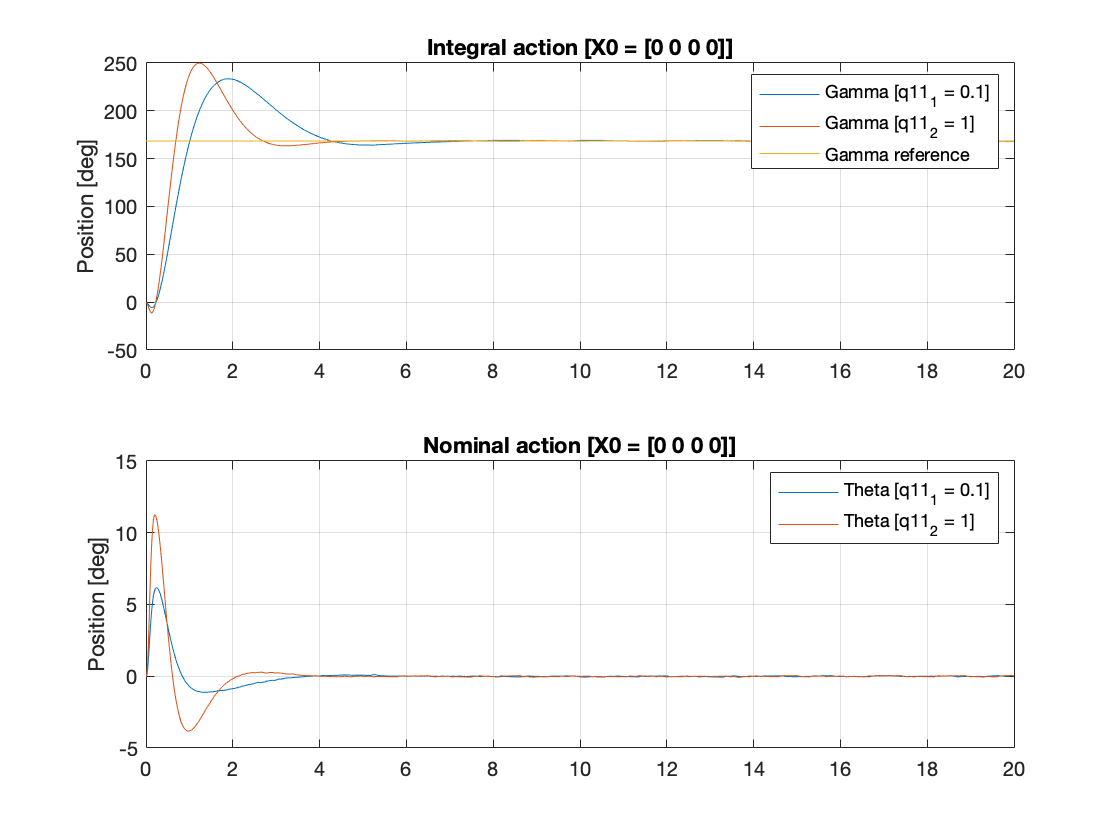

%% k1
% Set parameters
set_param('BalRobModel', ...
    'SolverType', 'Fixed-step', ...
    'Solver', 'FixedStepAuto', ...
    'StopTime', '20');
% Reference
set_param('BalRobModel/gam_ref [deg]','Value','0.1/wheel.r*rad2deg');

% State-space Controller
set_param('BalRobModel/Enable Integral','Value','1'); % Integral action ON
set_param('BalRobModel/State-space Controller/Input feedforward gain','gain','Nu'); % Input feedforward gain
set_param('BalRobModel/State-space Controller/State feedforward gain','gain','Nx'); % State feedforward gain
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_robust.K_1'); % State feedback gain
set_param('BalRobModel/State-space Controller/Ki','Gain','lqr_robust.Ki_1'); % Integral gain;
set_param('BalRobModel/State-space Controller/Discrete-Time Integrator','IntegratorMethod','Accumulation: Forward Euler'); % Integral gain;

% Initial conditions
lqr_nominal.x0 = [0 0 0 0]; % [deg]
set_param('BalRobModel/X0 [deg]','Value','lqr_nominal.x0'); % x0 = [0 0 0 0]

% Disturbance
set_param('BalRobModel/Disturbance','Time','10','Before','0','After','0'); % No disturbance

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_robust.t1 = simres.time; % Time vector 
lqr_robust.gam1 = simres.signals(1).values(:,1); % Gamma
lqr_robust.thh1 = simres.signals(1).values(:,2); % Theta
lqr_robust.refgam1 = simres.signals(1).values(:,3); % Ref gamma

%% K2
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_robust.K_2'); % State feedback gain
set_param('BalRobModel/State-space Controller/Ki','Gain','lqr_robust.Ki_2'); % Integral gain;

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_robust.t2 = simres.time; % Time vector 
lqr_robust.gam2 = simres.signals(1).values(:,1); % Gamma
lqr_robust.thh2 = simres.signals(1).values(:,2); % Theta
lqr_robust.refgam2 = simres.signals(1).values(:,3); % Ref gamma

% Plot simulation results
figure
subplot(2,1,1)
plot(lqr_robust.t1, lqr_robust.gam1);
hold on;
plot(lqr_robust.t2, lqr_robust.gam2);
hold on;
plot(lqr_robust.t2, lqr_robust.refgam2);
ylabel('Position [deg]');
grid on;
title('Integral action [X0 = [0 0 0 0]]');
legend('Gamma [q11_1 = 0.1]', 'Gamma [q11_2 = 1]', 'Gamma reference');

subplot(2,1,2)
plot(lqr_robust.t1, lqr_robust.thh1);
hold on;
plot(lqr_robust.t2, lqr_robust.thh2);
ylabel('Position [deg]');
grid on;
title('Nominal action [X0 = [0 0 0 0]]');
legend('Theta [q11_1 = 0.1]', 'Theta [q11_2 = 1]');

#### Simulation results $\bf{X_0 = [0 \ 0 \ 0 \ 0]}$, [Disturbance = 5V]

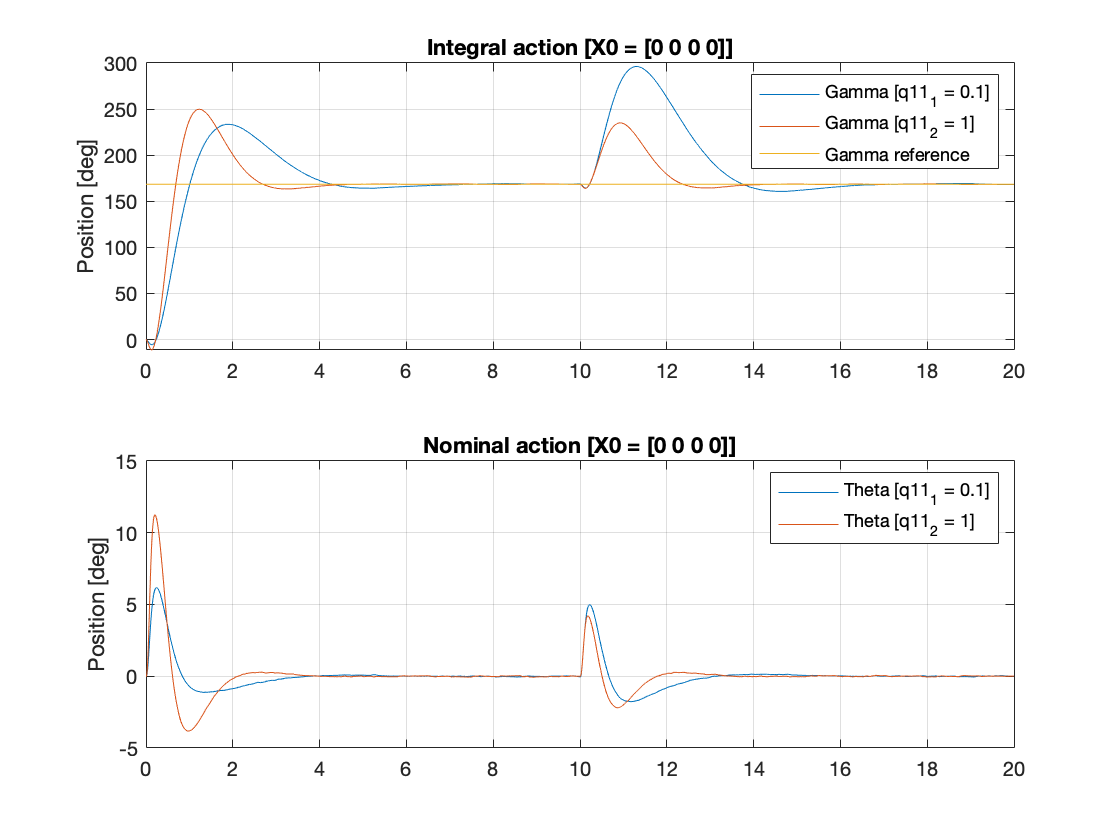

%% k1
% Set parameters
set_param('BalRobModel', ...
    'SolverType', 'Fixed-step', ...
    'Solver', 'FixedStepAuto', ...
    'StopTime', '20');
% Reference
set_param('BalRobModel/gam_ref [deg]','Value','0.1/wheel.r*rad2deg');

% State-space Controller
set_param('BalRobModel/Enable Integral','Value','1'); % Integral action ON
set_param('BalRobModel/State-space Controller/Input feedforward gain','gain','Nu'); % Input feedforward gain
set_param('BalRobModel/State-space Controller/State feedforward gain','gain','Nx'); % State feedforward gain
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_robust.K_1'); % State feedback gain
set_param('BalRobModel/State-space Controller/Ki','Gain','lqr_robust.Ki_1'); % Integral gain;
set_param('BalRobModel/State-space Controller/Discrete-Time Integrator','IntegratorMethod','Accumulation: Forward Euler'); % Integral gain;

% Initial conditions
lqr_nominal.x0 = [0 0 0 0]; % [deg]
set_param('BalRobModel/X0 [deg]','Value','lqr_nominal.x0'); % x0 = [0 0 0 0]

% Disturbance
set_param('BalRobModel/Disturbance','Time','10','Before','0','After','5/drv.duty2V'); % Disturbance = 5V

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_robust.t1 = simres.time; % Time vector 
lqr_robust.gam1 = simres.signals(1).values(:,1); % Gamma
lqr_robust.thh1 = simres.signals(1).values(:,2); % Theta
lqr_robust.refgam1 = simres.signals(1).values(:,3); % Ref gamma

%% K2
set_param('BalRobModel/State-space Controller/State feedback gain','gain','lqr_robust.K_2'); % State feedback gain
set_param('BalRobModel/State-space Controller/Ki','Gain','lqr_robust.Ki_2'); % Integral gain;

% Run simulation
sim('BalRobModel');

% Extract simulation results
lqr_robust.t2 = simres.time; % Time vector 
lqr_robust.gam2 = simres.signals(1).values(:,1); % Gamma
lqr_robust.thh2 = simres.signals(1).values(:,2); % Theta
lqr_robust.refgam2 = simres.signals(1).values(:,3); % Ref gamma

% Plot simulation results
figure
subplot(2,1,1)
plot(lqr_robust.t1, lqr_robust.gam1);
hold on;
plot(lqr_robust.t2, lqr_robust.gam2);
hold on;
plot(lqr_robust.t2, lqr_robust.refgam2);
ylabel('Position [deg]');
grid on;
title('Integral action [X0 = [0 0 0 0]]');
legend('Gamma [q11_1 = 0.1]', 'Gamma [q11_2 = 1]', 'Gamma reference');

subplot(2,1,2)
plot(lqr_robust.t1, lqr_robust.thh1);
hold on;
plot(lqr_robust.t2, lqr_robust.thh2);
ylabel('Position [deg]');
grid on;
title('Nominal action [X0 = [0 0 0 0]]');
legend('Theta [q11_1 = 0.1]', 'Theta [q11_2 = 1]');